# Material reproduction of piDMD via LSUN

References

- Baddoo Peter J., Herrmann Benjamin, McKeon Beverley J., Nathan Kutz J. and Brunton Steven L. 2023Physics-informed dynamic mode decompositionProc. R. Soc. A.4792022057620220576, [http://doi.org/10.1098/rspa.2022.0576](http://doi.org/10.1098/rspa.2022.0576)

- Brunton, S. L., & Kutz, J. N. (2022). *Data-Driven Science and Engineering: Machine Learning, Dynamical Systems, and Control* (2nd ed.). Cambridge: Cambridge University Press.

- jitKutz JN, Brunton SL, Brunton BW, Proctor JL. 2016 *Dynamic mode decomposition: data-driven modeling of complex systems*. Philadelphia, PA: SIAM.

clear 
close all
setup

databook_matlab-master exists.
databook_DATA exists.
DATA exists.
Copying VORTALL.mat ...
piDMD-main exists.
Add path piDMD-main/src


isDisplayTraining = false;
isVisualize = true;

## Source Data Preparation

nrows = 199;
ncols = 449;
load("../../../data/databook_DATA/DATA/VORTALL");
ut = reshape(VORTALL,nrows,ncols,[]);

## Source Data Visualization

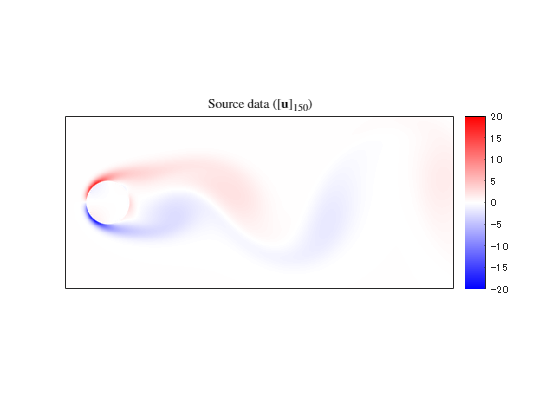

if isVisualize
    clims = 1.1*[min(ut,[],'all') max(ut,[],'all')];
    him = [];
    iFrame = 151;
    x = ut(:,:,iFrame);
    fcn_cylinderplot(him,x,clims);
    title("Source data (" + "$[\mathbf{u}]_{"+num2str(iFrame-1)+"}$)","Interpreter","latex")
    drawnow
    % exportgraphics
end

## TODO: Evaluate with PARFEVAL for multiple combinations of configuration parameters 

## piDMD setup

methodlist{1} = [ false, "exact" ];
methodlist{2} = [ false, "orthogonal" ];
methodlist{3} = [ true, "orthogonal" ];

## Parameter Setup

nModes4PODtrunc = 15;
nCoefs4LSUNtrunc = 2; % TODO: vary
snRatio = 0.2; % TODO: vary

## Noisy Data Preparation

Noise energy set to snRaio*100% of signal energy

varu = var(ut,0,'all');
varw = snRatio*varu;
sigmaw = sqrt(varw);
vt = ut + sigmaw * randn(size(ut),'like',ut);

## Noisy Data Visualization

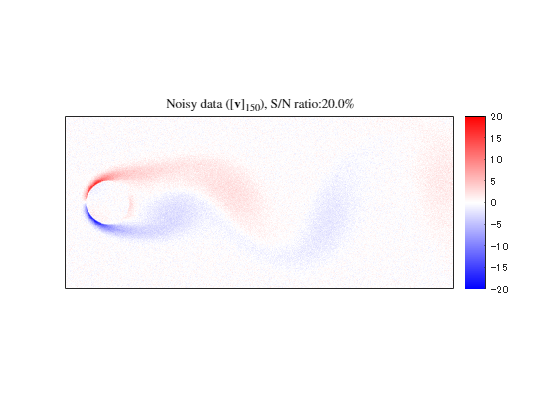

if isVisualize
    him = [];
    x = vt(:,:,iFrame);
    fcn_cylinderplot(him,x,clims);
    title("Noisy data  (" + "$[\mathbf{v}]_{"+num2str(iFrame-1)+"}$), S/N ratio:"+ num2str(100*snRatio,"%4.1f")+"\%","Interpreter","latex")
    drawnow
    % exportgraphics
    % save("../../../results/noisyflow_"+replace(num2str(sigmaw),'.','_'),"ut","vt")
end

islsun: false


exact


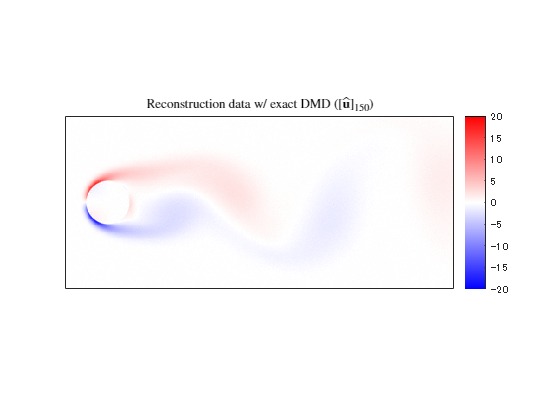

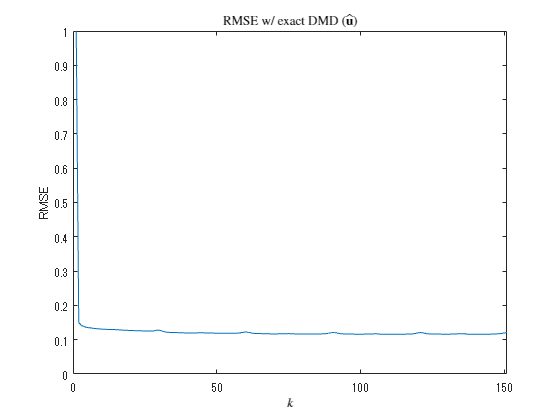

islsun: false


orthogonal


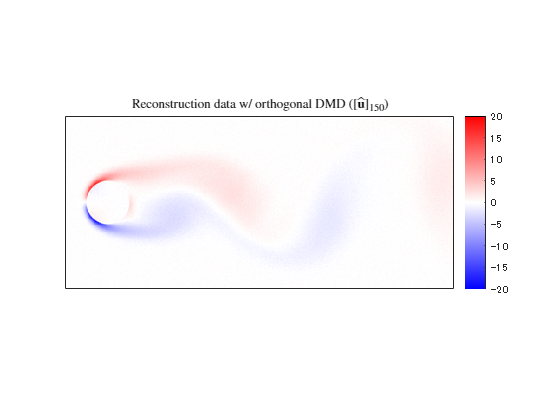

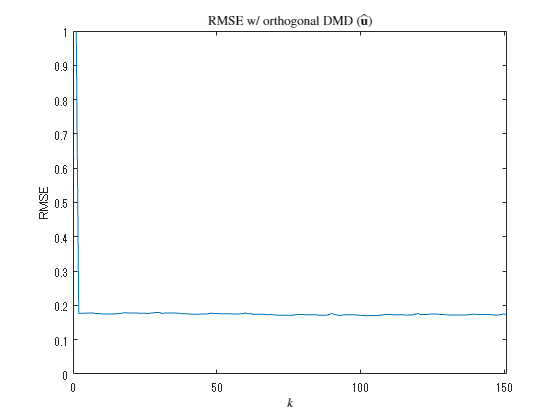

islsun: true


orthogonal


              stride: [4 4]
          ovlpFactor: [5 5]
              nCoefs: 2
           maxEpochs: 4
       miniBatchSize: 5
          stdInitAng: 1.0000e-06
         noDcLeakage: 0
        sgditeration: 0.0100
         sgdmomentum: 0.9000
            sgddecay: 0.0100
    initialLearnRate: 1.0000e-04
       lineLossTrain: []
              useGPU: 1



LSUN training ...
LSUN encoding ...
Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vh3 to Lv1_Cmp1_Vh3~
Copy angles from Lv1_Cmp1_Vh4 to Lv1_Cmp1_Vh4~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~
Copy angles from Lv1_Cmp1_Vv3 to Lv1_Cmp1_Vv3~
Copy angles from Lv1_Cmp1_Vv4 to Lv1_Cmp1_Vv4~
Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
LSUN decoding ...


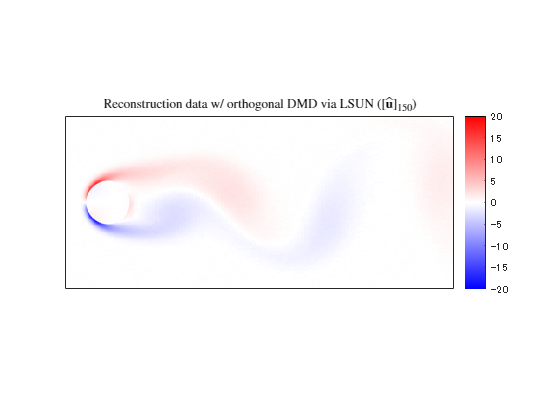

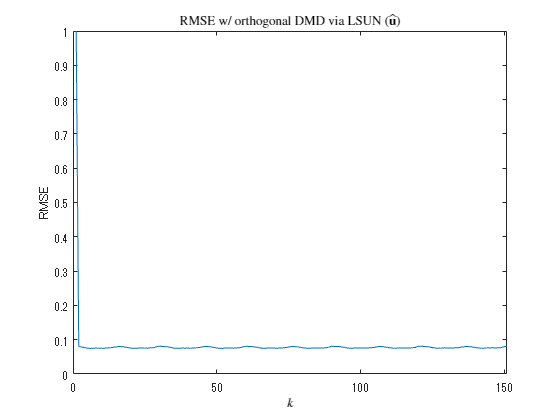

for imethod = 1:length(methodlist)
    islsun = strcmp(methodlist{imethod}(1),"true");
    disp("islsun: "+islsun)
    dmdmethod = methodlist{imethod}(2);
    disp(dmdmethod)

    % Get default options
    [~,~,~,~,options] = fcn_pidmdvialsun([],[],[],islsun);

    if isDisplayTraining && islsun
        figure
        lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
        ylim([0 inf])
        xlabel("Iteration")
        ylabel("Loss")
        grid on
        options.lineLossTrain = lineLossTrain;
    end
    disp(options)

    % Conduct DMD
    %[dmdA, dmdVals, dmdVecs, dmdProjA,~,rt] = fcn_pidmdvialsun(vt,dmdmethod,nModes4PODtrunc,islsun,options);
    [rt,rmse] = myfunc_(vt,ut,dmdmethod,nModes4PODtrunc,islsun,options);

    % Visualization
    if isVisualize
        if islsun
            strlsun = "via LSUN ";
        else
            strlsun = " ";
        end
        figure
        him = [];
        x = rt(:,:,iFrame);
        fcn_cylinderplot(him,x,clims);
        title("Reconstruction data w/ "+dmdmethod+" DMD "+ strlsun +"(" + "$[\hat{\mathbf{u}}]_{"+num2str(iFrame-1)+"}$)","Interpreter","latex")
        drawnow
        % exportgraphics

        figure
        plot(rmse)
        axis([0 length(rmse) 0 1])
        title("RMSE w/ "+dmdmethod+" DMD "+ strlsun +"(" + "$\hat{\mathbf{u}}$)","Interpreter","latex")
        xlabel("$k$","Interpreter","latex")
        ylabel("RMSE")
        drawnow
        % exportgraphics
    end

end

## Function for evaluation

function [rt,rmse] = myfunc_(vt,ut,dmdmethod,nModes4PODtrunc,islsun,options)
    %[dmdA, dmdVals, dmdVecs, dmdProjA,~,rt] = fcn_pidmdvialsun(vt,dmdmethod,nModes4PODtrunc,islsun,options);
    [~,~,~,~,~,rt] = fcn_pidmdvialsun(vt,dmdmethod,nModes4PODtrunc,islsun,options);
    rmse = squeeze(sqrt(mean((rt-ut).^2,[1 2])));
end
